# Final Project Owen + Gracy ES115 Robot Speed and Steering Telemetry Analyzer

%{
ES115
originally from Final Project Bank, Project #2
Authors: Gracy Sylvestre, Owen Rogg
Date: 2026-04-24
Purpose:
Use a dataset with time, velocity, steering angle (real or synthetic)
Smooth noisy signals and compute turning events, stop events, and average
speed.
Visualize velocity vs time, steering vs time, scatter steering vs speed,
histogram of speed.
Define a "driving quality score" from 2-3 metrics

Describe input values (Knowns)and required output (Unknowns)
Input:
- Time vector data points, moving window, turning threshold
Output:
- Plots of steering vs time, velocity vs time, histogram, scatter, and
driving metrics.


MATLAB tools/functions:
Figure
Subplot
Tiledlayout
Inputdlg
Menu
Sum
Movmean
Diff
Table

Reflection After Completing the Project:
- What did you learn?
How to set up a dashboard for selection of desired plots, and determining
spikes in a dataset and utilizing user input within functions to customize
output.
- What could be done differently?
Finding real telemetry instead of producing synthetic datapoints
- Rate the project difficulty (1 - 10)
5.5
%}




%clear everything for a fresh start
clear
clc
close all

dt = input("Enter number of data points (e.g., 75): "); % dataset size
if isempty(dt); dt = 75; end % default value

Moving_window = input("Enter moving average window size (e.g., 15): "); % moving window selection
if isempty(Moving_window); Moving_window = 15; end %default value

stop = input("Enter stop threshold (e.g., 0.1): "); % define stop threshold
if isempty(stop); stop = 0.1; end %default value

turn = input("Enter turning threshold in degrees (e.g., 15): "); %define turn threshold
if isempty(turn); turn = 15; end %default value

%time vector
t=[1:dt]';
%velocity for both runs
velocityRun1 = rand(size(t)) * 10;

velocityRun1 =     8.1691
    1.8947
    1.2369
    8.2100
    6.3790
    0.1612
    8.9595
    5.1538
    5.4452
    6.0644
    7.6044
    8.5535
    3.8287
    0.8465
    7.3387


velocityRun2 = rand(size(t)) * 10;

velocityRun2 =     7.7149
    7.6479
    4.2107
    0.5681
    5.8575
    1.7416
    7.2861
    5.3429
    2.5306
    9.1706
    7.5819
    8.8703
    0.6880
    1.8353
    7.3707


%steering angle for both runs
steeringAngleRun1 = -15 + rand(size(t)) * 30;

steeringAngleRun1 =    11.8923
   -0.5331
  -14.5772
    3.6864
   -8.0671
    0.8230
    6.7498
    3.2225
    2.6510
   -1.9970
   -7.6748
   -2.1312
  -14.6947
    3.2646
   13.7393


steeringAngleRun2 = -15 + rand(size(t)) * 30;

steeringAngleRun2 =     2.4729
   -2.3698
  -12.2379
  -14.2792
   -0.2656
   -6.6520
   -4.8073
   -6.3795
   -9.8729
   -3.0221
    5.9295
   -8.8897
    4.9898
   -1.7080
   -2.0011




% Calculate the average velocity and steering angle over the moving window
avgVelocityRun1 = movmean(velocityRun1, Moving_window);
avgVelocityRun2 = movmean(velocityRun2, Moving_window);

avgSteeringAngleRun1 = movmean(steeringAngleRun1, Moving_window);
avgSteeringAngleRun2 = movmean(steeringAngleRun2, Moving_window);

%stop events (velocity low)
stopEventsRun1 = sum(avgVelocityRun1 < stop);
stopEventsRun2 = sum(avgVelocityRun2 < stop);

% turning events (magnitude high)
turnEventsRun1 = sum(abs(avgSteeringAngleRun1 > turn));
turnEventsRun2 = sum(abs(avgSteeringAngleRun2 > turn));


% Display smooth signal results
if var(avgVelocityRun1) < var(velocityRun1)
fprintf("\nRun 1 smoothing validated (variance reduced)\n");
else
fprintf("\nRun 1 smoothing may be incorrect\n");
end


Run 1 smoothing validated (variance reduced)



if var(avgVelocityRun2) < var(velocityRun2)
fprintf("Run 2 smoothing validated (variance reduced)\n");
else
fprintf("Run 2 smoothing may be incorrect\n");
end

Run 2 smoothing validated (variance reduced)


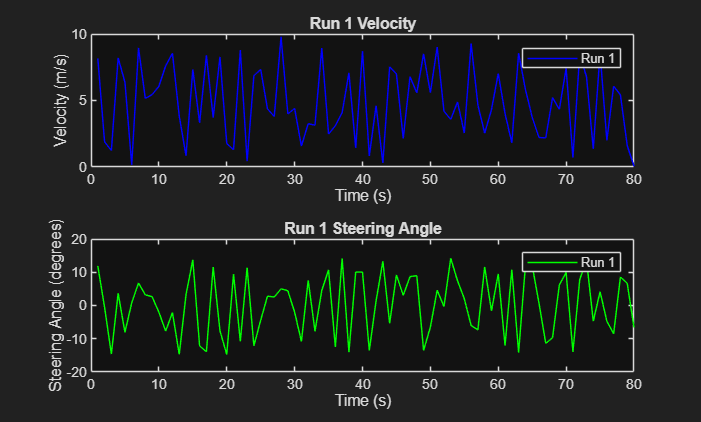


%values (average speed)
avgSpeed1 = mean(avgVelocityRun1);
avgSpeed2 = mean(avgVelocityRun2);

% find sudden changes (spikes)
spikeThreshold = 7;
spikesRun1 = sum(abs(diff(avgSteeringAngleRun1)) > spikeThreshold);
spikesRun2 = sum(abs(diff(avgSteeringAngleRun2)) > spikeThreshold);

% smoothness metric
smoothness1 = var(velocityRun1) / var(avgVelocityRun1);
smoothness2 = var(velocityRun2) / var(avgVelocityRun2);

%create plots for velocity in each run and steering angle
bothrunplot=figure(Visible='off');
subplot(2, 1, 1);
tiledlayout(2,1);
nexttile;
plot(t, velocityRun1, 'b', t, velocityRun2, 'r');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Comparison');
legend('Run 1', 'Run 2');
nexttile;
plot(t, steeringAngleRun1, 'g', t, steeringAngleRun2, 'm');
xlabel('Time (s)');
ylabel('Steering Angle (degrees)');
title('Steering Angle Comparison');
legend('Run 1', 'Run 2');
saveas(bothrunplot,'bothrun','fig')

%plot for run one
runoneplot=figure(Visible='off');
subplot(2, 1, 1);
tiledlayout(2,1);
nexttile;
plot(t, velocityRun1, 'b');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Run 1 Velocity');
legend('Run 1');
saveas(runoneplot, 'runone', 'fig');
nexttile
plot(t,steeringAngleRun1,'g')
xlabel('Time (s)');
ylabel('Steering Angle (degrees)');
title('Run 1 Steering Angle');
legend('Run 1');
saveas(runoneplot, 'runone_steering', 'fig');

%plot for run two
runtwoplot=figure(Visible='off');
subplot(2,1,1);
tiledlayout(2,1);
nexttile;
plot(t,velocityRun2, 'r')
xlabel('Time(s)')
ylabel('Velocity(m/s')
title('Velocity Run Two')
nexttile;
plot(t, steeringAngleRun2, 'm');
xlabel('Time (s)');
ylabel('Steering Angle (degrees)');
title('Run 2 Steering Angle');
legend('Run 2');
saveas(runtwoplot, 'runTwo_steering', 'fig');

%scatter plot
splot=figure(Visible='off');
scatter(velocityRun1,steeringAngleRun1,'blue','o');
grid on
hold on;
scatter(velocityRun2,steeringAngleRun2,'red','o');
xlabel('Velocity(m/s)');
ylabel('Steering Angle(degrees)');
title('Scatter Plot of Velocity Vs Steering Angle');
legend('Run 1','Run 2','Location','best');
saveas(splot,'splot','fig');

%histogram of speed and steering for each run
histplot=figure(Visible='off');
subplot(2,2,1)
tiledlayout(2,2)
nexttile;
histogram(velocityRun1, 'FaceColor', 'b', 'EdgeColor', 'k');
xlabel('Velocity (m/s)');
ylabel('Frequency');
title('Histogram of Velocity for Run 1');
nexttile;
histogram(velocityRun2, 'FaceColor', 'r', 'EdgeColor', 'k');
xlabel('Velocity (m/s)');
ylabel('Frequency');
title('Histogram of Velocity for Run 2');
nexttile;
histogram(steeringAngleRun1,'FaceColor','b','EdgeColor','k');
xlabel('Steering Angle(degrees)');
ylabel('Frequency');
title('Histogram of Steering Angle for Run 1');
nexttile;
histogram(steeringAngleRun2, 'FaceColor', 'r', 'EdgeColor', 'k');
xlabel('Steering Angle (degrees)');
ylabel('Frequency');
title('Histogram of Steering Angle for Run 2');
saveas(histplot,'histplot','fig')

%ask for which plots they would like to see
choice = menu('What run would you like to view?','Both Runs','Run 1','Run 2','Scatter Plot','Histogram','All Data');
switch choice
case 0
disp("Goodbye!")
case 1
open("bothrun.fig")
set(bothrunplot,'Visible','on')
case 2
open("runone.fig")
set(runoneplot,'Visible','on')
case 3
open("runTwo_steering.fig")
set(runtwoplot,'Visible','on')
case 4
open("splot.fig")
set(splot,'Visible','on')
case 5
open("histplot.fig")
set(histplot, 'visible', 'on');
case 6
open("bothrun.fig")
open("runone.fig")
open("runTwo_steering.fig")
open("splot.fig")
open("histplot.fig")
set(bothrunplot,'Visible','on')
set(runoneplot,'Visible','on')
set(runtwoplot,'Visible','on')
set(splot,'Visible','on')
set(histplot, 'visible', 'on');
end


%driving quality score

% 1. Smoothness Score for both runs(reduce variance)
smoothScore1 = 1 / (1 + var(diff(avgVelocityRun1)));
smoothScore2 = 1 / (1 + var(diff(avgVelocityRun2)));

% 2. Steering Spike Score for both runs (want least amount of spikes as possible)
steeringScore1 = 1 / (1 + spikesRun1);
steeringScore2 = 1 / (1 + spikesRun2);

% 3. Stop Event Score for both runs (aim: least amount of stops as possible)
stopScore1 = 1 / (1 + stopEventsRun1);
stopScore2 = 1 / (1 + stopEventsRun2);

% Final weighted driving quality score for both runs(0–100)
DQ1 = 100 * (0.4 * smoothScore1 + 0.3 * steeringScore1 + 0.3 * stopScore1);
DQ2 = 100 * (0.4 * smoothScore2 + 0.3 * steeringScore2 + 0.3 * stopScore2);

% Display results for both runs
fprintf("\n DRIVING QUALITY SCORES \n");
fprintf("Run 1 Driving Quality Score: %.2f / 100\n", DQ1);
fprintf("Run 2 Driving Quality Score: %.2f / 100\n\n", DQ2);

% Driving interpretation for both runs
if DQ1 > 80 %if score is greater than 80, control is above average
fprintf("Run 1 Behavior: Excellent control\n");
elseif DQ1 > 60 %if score is greater than 60, control is average
fprintf("Run 1 Behavior: Moderate control\n");
elseif DQ1 > 40 %if score is greater than 40, control is relatively below average
fprintf("Run 1 Behavior: Rough driving\n");
else %if score is below 40 control is extremely below average
fprintf("Run 1 Behavior: Poor control\n");
end

if DQ2 > 80
fprintf("Run 2 Behavior: Excellent control\n");
elseif DQ2 > 60
fprintf("Run 2 Behavior: Moderate control\n");
elseif DQ2 > 40
fprintf("Run 2 Behavior: Rough driving\n");
else
fprintf("Run 2 Behavior: Poor control\n");
end
%table
results = table(t, avgVelocityRun1, avgVelocityRun2, ...
avgSteeringAngleRun1, avgSteeringAngleRun2);
'VariableNames', {'time','avgVelocityRun1','avgVelocity2'};

ans = 'VariableNames'

ans = 1×3 cell array
    {'time'}    {'avgVelocityRun1'}    {'avgVelocity2'}
